**Taller Integrador: Diseño de compensadores Clasicos**

Integrantes:

Daniel Felipe Sarmiento Pilonieta - 2202797

Monica Cristina Peña Rincon - 2205125

Fabian Andres Amador Ballesteros - 2204215

- **Ejercicio 1: Compensador en adelanto (LGR)**


%  EJERCICIO 1 - Compensador en Adelanto por LGR
%  Planta: G1(s) = 1 / [s(s+2)(s+5)]

%  Especificaciones:
%       Mp <= 15%
%       Ts <= 2 s
%  Método:
%       Diseño por Lugar Geométrico de las Raíces (LGR)


% 1. DEFINICIÓN DE LA PLANTA


Gp = zpk([], [0 -2 -5], 1);

% 2. SISTEMA SIN COMPENSAR


Glc0 = feedback(Gp, 1);
info0 = stepinfo(Glc0);


% 3. TRADUCCIÓN DE ESPECIFICACIONES

Mp_max = 0.15;

% cálculo de zeta a partir del Mp
zeta = -log(Mp_max) / sqrt(pi^2 + log(Mp_max)^2);

% usamos margen para asegurar cumplimiento
sigma_d = (4 / 2) * 1.1;

wn_d = sigma_d / zeta;
wd_d = wn_d * sqrt(1 - zeta^2);

sd = -sigma_d + 1j * wd_d;


% 4. CONDICIÓN DE ÁNGULO

ang_p0 = angle(sd - 0) * 180/pi;
ang_p2 = angle(sd + 2) * 180/pi;
ang_p5 = angle(sd + 5) * 180/pi;

ang_planta = -(ang_p0 + ang_p2 + ang_p5);
ang_faltante = -180 - ang_planta;


% 5. DISEÑO DEL COMPENSADOR


zc = 2; % Se ubica el cero cerca del polo en -2 para aportar fase
ang_zc = angle(sd + zc) * 180/pi;

ang_pc = ang_zc - ang_faltante;

pc = sigma_d + wd_d / tan(ang_pc * pi/180);


% 6. GANANCIA DEL COMPENSADOR


Gc_unit = tf([1 zc], [1 pc]);
Kc = 1 / abs(evalfr(Gc_unit * Gp, sd));

Gc = tf(Kc * [1 zc], [1 pc]);


% 7. SISTEMA COMPENSADO


Glcc = feedback(Gc * Gp, 1);
infoC = stepinfo(Glcc);


% 8. RESULTADOS ORGANIZADOS (TIPO TABLA)


fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 1\n')

              RESULTADOS - EJERCICIO 1


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Mp <= 15%%   |   Ts <= 2 s\n')

Mp <= 15%   |   Ts <= 2 s



fprintf('\nPARAMETROS DE DISEÑO:\n')


PARAMETROS DE DISEÑO:


fprintf('zeta = %.4f | sigma = %.4f\n', zeta, sigma_d)

zeta = 0.5169 | sigma = 2.2000


fprintf('wn   = %.4f | wd    = %.4f\n', wn_d, wd_d)

wn   = 4.2559 | wd    = 3.6432


fprintf('sd   = %.4f + j%.4f\n', real(sd), imag(sd))

sd   = -2.2000 + j3.6432



fprintf('\nCOMPENSADOR:\n')


COMPENSADOR:


fprintf('Gc(s) = %.4f (s + %.4f)/(s + %.4f)\n', Kc, zc, pc)

Gc(s) = 637.3391 (s + 2.0000)/(s + 34.5876)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('           COMPARACION DE DESEMPEÑO\n')

           COMPARACION DE DESEMPEÑO


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15s %-15s %-10s\n', 'Parametro', 'Sin Comp.', 'Con Comp.', 'Spec')

Parametro                 Sin Comp.       Con Comp.       Spec      


fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f %-10s\n', 'Mp (%)', ...
    info0.Overshoot, infoC.Overshoot, '<=15')

Mp (%)                    0.00            14.87           <=15      



fprintf('%-25s %-15.4f %-15.4f %-10s\n', 'Ts (s)', ...
    info0.SettlingTime, infoC.SettlingTime, '<=2')

Ts (s)                    36.9727         1.8721          <=2       



fprintf('%-25s %-15.4f %-15.4f\n', 'Tp (s)', ...
    info0.PeakTime, infoC.PeakTime)

Tp (s)                    67.7698         0.9001         



fprintf('%-25s %-15.4f %-15.4f\n', 'Tr (s)', ...
    info0.RiseTime, infoC.RiseTime)

Tr (s)                    20.3836         0.3971         



fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------




% 9. ERROR EN RÉGIMEN PERMANENTE


Kv_sin = dcgain(tf([1 0], 1) * Gp);
Kv_con = dcgain(tf([1 0], 1) * Gc * Gp);

fprintf('\nERROR EN REGIMEN PERMANENTE (RAMPA):\n')


ERROR EN REGIMEN PERMANENTE (RAMPA):


fprintf('%-25s %-15.4f %-15.4f\n', 'Kv', Kv_sin, Kv_con)

Kv                        0.1000          3.6854         


fprintf('%-25s %-15.4f %-15.4f\n', 'ess', 1/Kv_sin, 1/Kv_con)

ess                       10.0000         0.2713         


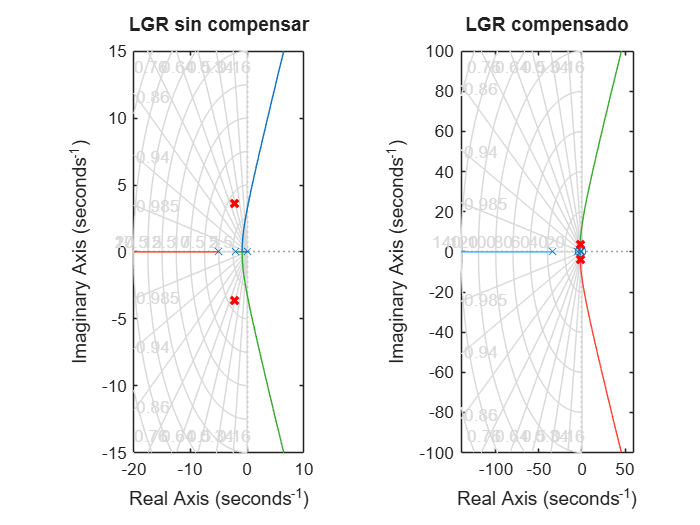



% 10. GRAFICAS


figure(1)
subplot(1,2,1)
rlocus(Gp)
hold on
plot(real(sd), imag(sd), 'rx','LineWidth',2)
plot(real(sd), -imag(sd), 'rx','LineWidth',2)
title('LGR sin compensar')
grid on

subplot(1,2,2)
rlocus(Gc*Gp)
hold on
plot(real(sd), imag(sd), 'rx','LineWidth',2)
plot(real(sd), -imag(sd), 'rx','LineWidth',2)
title('LGR compensado')
grid on

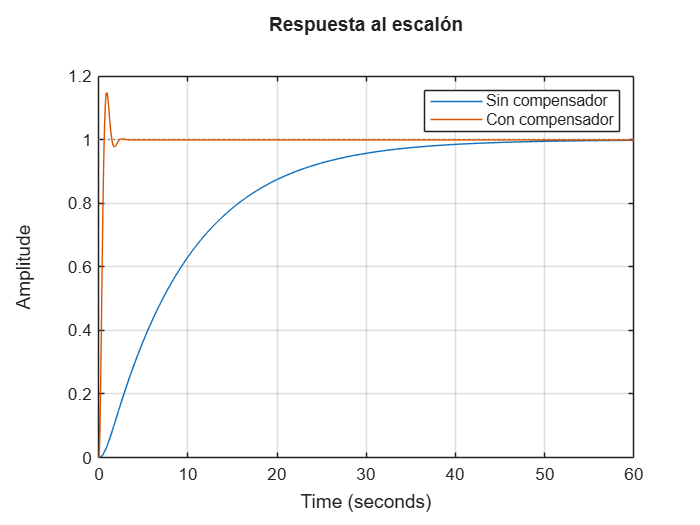


figure(2)
step(Glc0, Glcc)
legend('Sin compensador','Con compensador')
title('Respuesta al escalón')
grid on

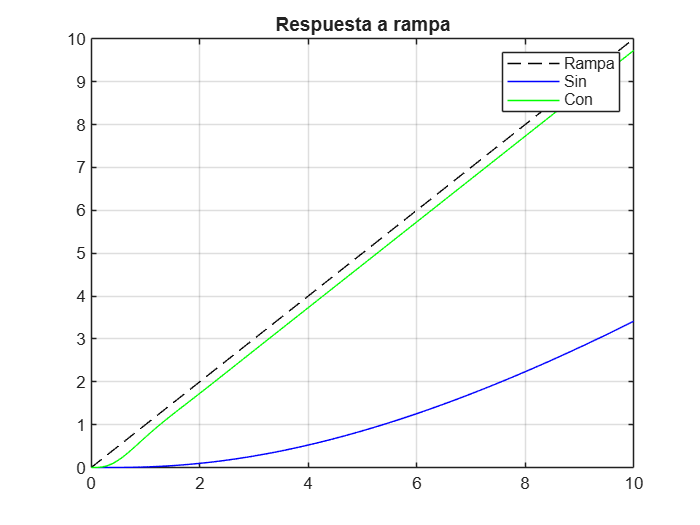


t = 0:0.01:10;
r = t;

y0 = lsim(Glc0, r, t);
yC = lsim(Glcc, r, t);

figure(3)
plot(t, r, 'k--', t, y0, 'b', t, yC, 'g')
legend('Rampa','Sin','Con')
title('Respuesta a rampa')
grid on

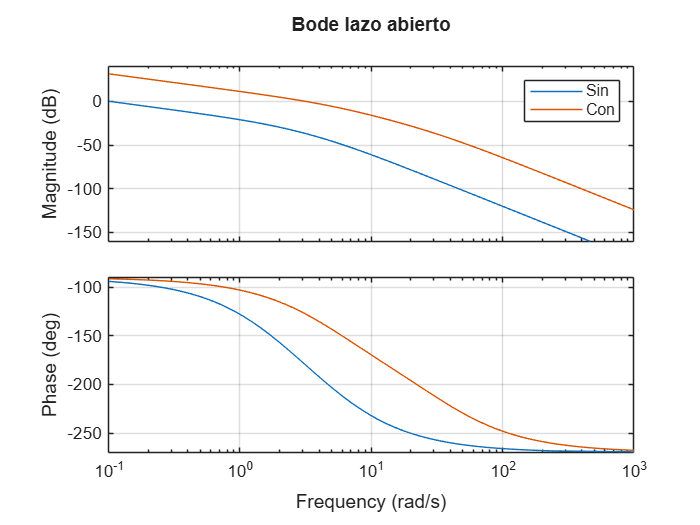


figure(4)
bode(Gp, Gc*Gp)
legend('Sin','Con')
title('Bode lazo abierto')
grid on

**2. Ejercicio 2: Compensador en adelanto (frecuencia)**

% ESPECIFICACIONES DEL PROBLEMA
% Se desea diseñar un compensador en adelanto que cumpla:

% 1. Margen de fase (PM):
%    PM >= 50°
  
% 2. Frecuencia de cruce de ganancia (wc):
%    wc ≈ 4 rad/s

clear; close all; clc;


% 1. PLANTA


Gp = tf(1, conv([1 0], conv([1 2], [1 5])));

wc = 4;   % frecuencia de cruce deseada


% 2. ANALISIS EN FRECUENCIA (SIN COMPENSAR)


[mag0, phase0] = bode(Gp, wc);
mag0 = squeeze(mag0);
phase0 = squeeze(phase0);

PM0 = 180 + phase0;


% 3. DISEÑO ANALITICO DEL COMPENSADOR


PMd = 50;

phi_m = PMd - PM0 + 5;   % margen de seguridad

phi_rad = deg2rad(phi_m);

alpha = (1 - sin(phi_rad)) / (1 + sin(phi_rad));

T = 1/(wc*sqrt(alpha));

zc = 1/T;
pc = 1/(alpha*T);

Gc = tf([1 zc],[1 pc]);


% 4. AJUSTE DE GANANCIA

[mag1, ~] = bode(Gc*Gp, wc);
mag1 = squeeze(mag1);

K = 1/mag1;

Gc = K*Gc;


% 5. SISTEMAS (COMPARACION CORRECTA)


G_total = Gc*Gp;

Glc0 = feedback(Gp,1);        %  SIN compensador 
Glcc = feedback(G_total,1);   % CON compensador


% 6. RESULTADOS EN FRECUENCIA


[GM0, PM_sin, ~, wc_sin] = margin(Gp);
[GMc, PM_con, ~, wc_con] = margin(G_total);


% 7. RESULTADOS TEMPORALES


info0 = stepinfo(Glc0);
infoC = stepinfo(Glcc);


% 8. ERROR EN ESTADO ESTACIONARIO


Kv0 = dcgain(tf([1 0],1)*Gp);
Kvc = dcgain(tf([1 0],1)*G_total);


fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 2\n')

              RESULTADOS - EJERCICIO 2


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('PM >= 50°   |   wc ≈ 4 rad/s\n')

PM >= 50°   |   wc ≈ 4 rad/s



fprintf('\nCOMPENSADOR DISEÑADO:\n')


COMPENSADOR DISEÑADO:


fprintf('Gc(s) = %.4f (s + %.4f)/(s + %.4f)\n', K, zc, pc)

Gc(s) = 565.3874 (s + 0.8104)/(s + 19.7442)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION EN FRECUENCIA\n')

         COMPARACION EN FRECUENCIA


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15s %-15s %-10s\n','Parametro','Sin Comp.','Con Comp.','Spec')

Parametro                 Sin Comp.       Con Comp.       Spec      


fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f %-10s\n','PM (°)',PM_sin,PM_con,'>=50')

PM (°)                    86.00           55.00           >=50      


fprintf('%-25s %-15.2f %-15.2f %-10s\n','wc (rad/s)',wc_sin,wc_con,'≈4')

wc (rad/s)                0.10            4.00            ≈4        



fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION TEMPORAL\n')

         COMPARACION TEMPORAL


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f\n','Mp (%)',info0.Overshoot,infoC.Overshoot)

Mp (%)                    0.00            7.66           


fprintf('%-25s %-15.4f %-15.4f\n','Ts (s)',info0.SettlingTime,infoC.SettlingTime)

Ts (s)                    36.9727         3.2069         


fprintf('%-25s %-15.4f %-15.4f\n','Tr (s)',info0.RiseTime,infoC.RiseTime)

Tr (s)                    20.3836         0.3356         



fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         ERROR EN REGIMEN PERMANENTE\n')

         ERROR EN REGIMEN PERMANENTE


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.4f %-15.4f\n','Kv',Kv0,Kvc)

Kv                        0.1000          2.3205         


fprintf('%-25s %-15.4f %-15.4f\n','ess',1/Kv0,1/Kvc)

ess                       10.0000         0.4309         



fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------


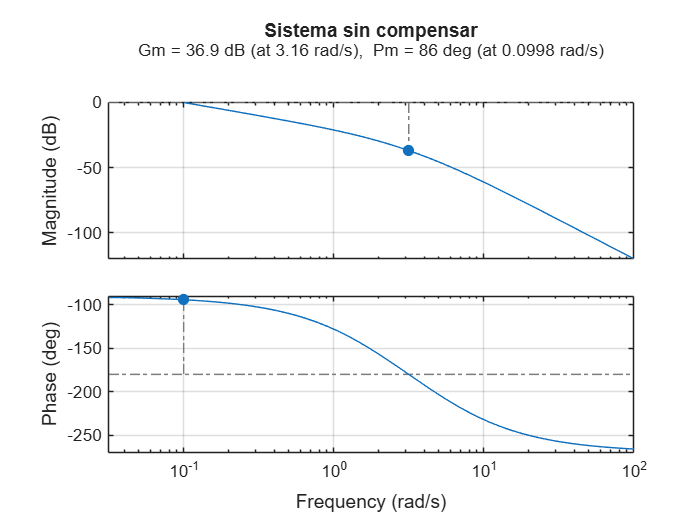



% 9. GRAFICAS 

figure(1)
margin(Gp)
title('Sistema sin compensar')
grid on

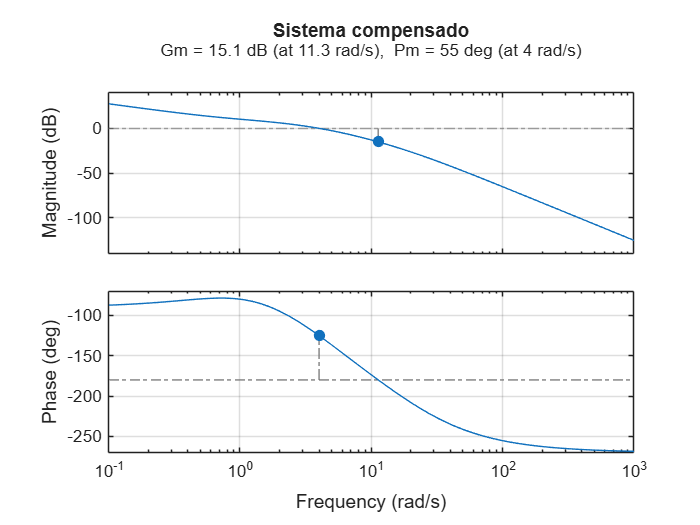


figure(2)
margin(G_total)
title('Sistema compensado')
grid on

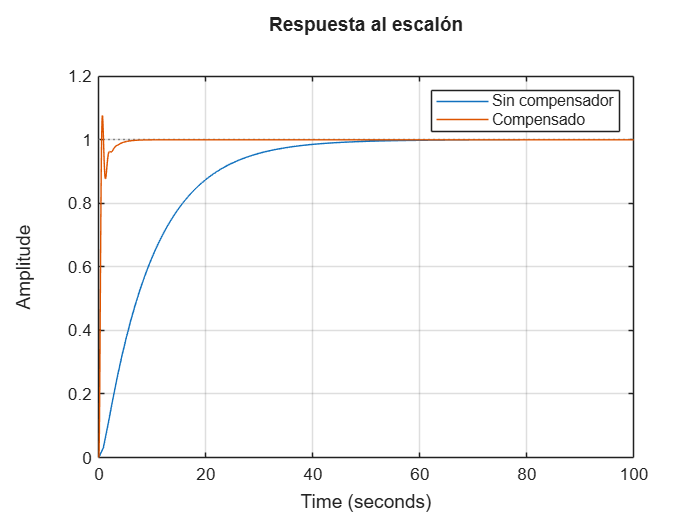


figure(3)
step(Glc0,Glcc,100)
legend('Sin compensador','Compensado')
title('Respuesta al escalón')
grid on

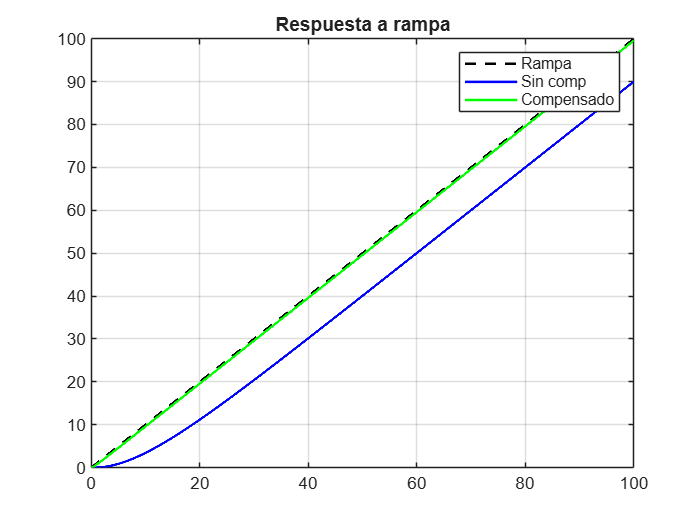


t=0:0.01:100;
r=t;

y0=lsim(Glc0,r,t);
yc=lsim(Glcc,r,t);

figure(4)
plot(t,r,'k--',t,y0,'b',t,yc,'g','LineWidth',1.5)
legend('Rampa','Sin comp','Compensado')
title('Respuesta a rampa')
grid on

**3.Ejercicio 3: Compensador en atraso (LGR)**

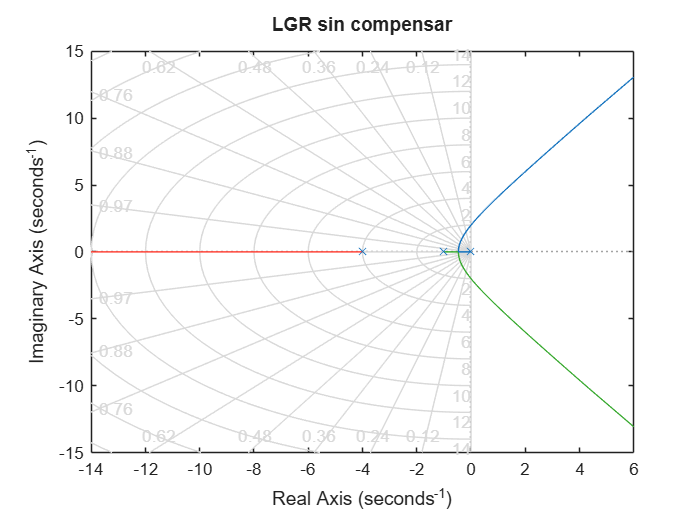

% EJERCICIO 3 - Compensador en Atraso (LGR)

% Planta: G(s) = 7 / [2s(s+1)(s+4)]

% Especificaciones:
%   Mp < 25%
%   ess <= 0.1 (rampa)

clear; close all; clc;

%% 1. PLANTA

Gp = tf(7, conv([2 0], conv([1 1],[1 4])));

%% 2. LGR PARA DISEÑO DINÁMICO

figure(1)
rlocus(Gp)
sgrid(0.4,[])   % linea de amortiguamiento (zeta ≈ 0.4)
title('LGR sin compensar')
grid on



K0 = 0.38;   % valor que cumple Mp < 25%

G0 = K0*Gp;
Glc0 = feedback(G0,1);
info0 = stepinfo(Glc0);

%% 3. ERROR SIN COMPENSAR

Kv0 = dcgain(tf([1 0],1)*G0);
ess0 = 1/Kv0;

%% 4. DISEÑO DEL COMPENSADOR EN ATRASO

Kv_deseado = 10;
beta = Kv_deseado / Kv0;

% Regla: cero y polo cercanos al origen
zc = 0.05;
pc = zc / beta;

Gc = tf([1 zc],[1 pc]);

%% 5. SISTEMA COMPENSADO

G_total = K0 * Gc * Gp;
Glcc = feedback(G_total,1);
infoC = stepinfo(Glcc);

%% 6. ERROR FINAL

KvC = dcgain(tf([1 0],1)*G_total);
essC = 1/KvC;

%% 7. RESULTADOS

fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 3\n')

              RESULTADOS - EJERCICIO 3


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Mp < 25%%   |   ess <= 0.1\n')

Mp < 25%   |   ess <= 0.1



fprintf('\nPARAMETROS:\n')


PARAMETROS:


fprintf('K0 = %.4f\n', K0)

K0 = 0.3800


fprintf('beta = %.4f\n', beta)

beta = 30.0752



fprintf('\nCOMPENSADOR:\n')


COMPENSADOR:


fprintf('Gc(s) = (s + %.4f)/(s + %.6f)\n', zc, pc)

Gc(s) = (s + 0.0500)/(s + 0.001663)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('COMPARACION DE DESEMPEÑO\n')

COMPARACION DE DESEMPEÑO


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-20s %-15s %-15s\n','Parametro','Sin Comp.','Con Comp.')

Parametro            Sin Comp.       Con Comp.      



fprintf('%-20s %-15.2f %-15.2f\n','Mp (%)', ...
    info0.Overshoot, infoC.Overshoot)

Mp (%)               1.81            14.91          



fprintf('%-20s %-15.4f %-15.4f\n','Ts (s)', ...
    info0.SettlingTime, infoC.SettlingTime)

Ts (s)               6.6856          41.3723        



fprintf('%-20s %-15.4f %-15.4f\n','Tr (s)', ...
    info0.RiseTime, infoC.RiseTime)

Tr (s)               4.2879          3.6299         



fprintf('\nERROR EN ESTADO ESTACIONARIO\n')


ERROR EN ESTADO ESTACIONARIO



fprintf('%-20s %-15.4f %-15.4f\n','Kv',Kv0,KvC)

Kv                   0.3325          10.0000        


fprintf('%-20s %-15.4f %-15.4f\n','ess',ess0,essC)

ess                  3.0075          0.1000         



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------


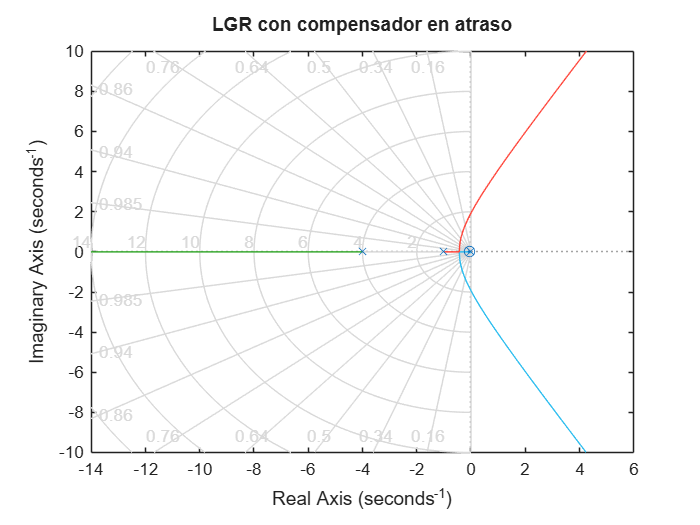


%% 8. GRAFICAS


figure(5)
rlocus(Gc*Gp)
sgrid(0.4,[])
title('LGR con compensador en atraso')
grid on

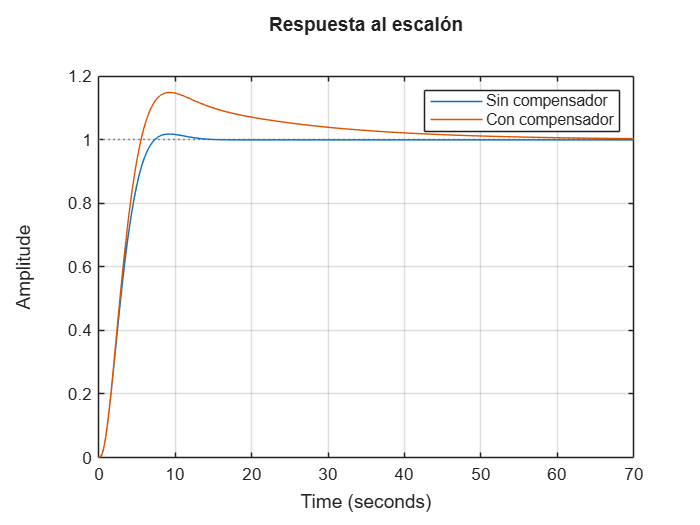


figure(2)
step(Glc0,Glcc)
legend('Sin compensador','Con compensador')
title('Respuesta al escalón')
grid on

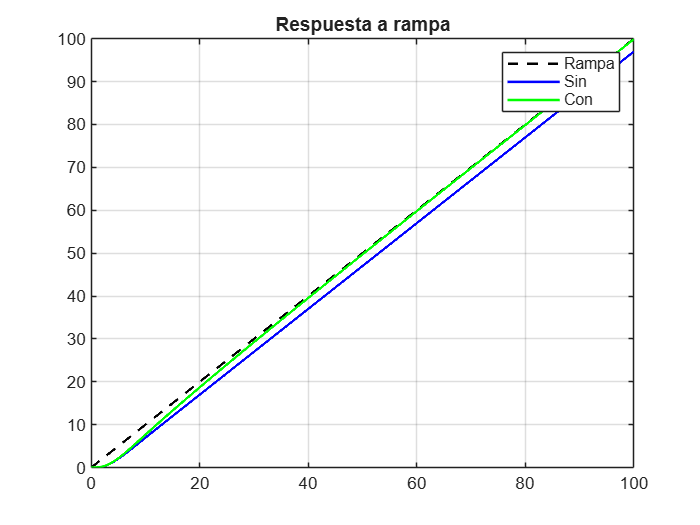


t = 0:0.01:100;
r = t;

y0 = lsim(Glc0,r,t);
yC = lsim(Glcc,r,t);

figure(3)
plot(t,r,'k--',t,y0,'b',t,yC,'g','LineWidth',1.5)
legend('Rampa','Sin','Con')
title('Respuesta a rampa')
grid on

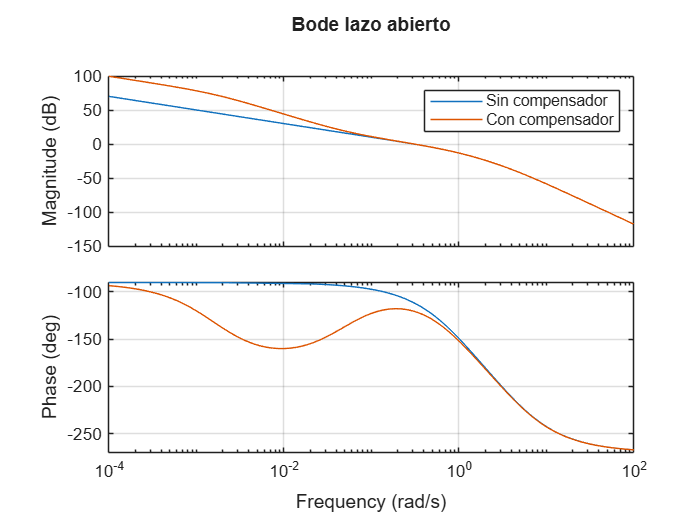


figure(4)
bode(G0, G_total)
legend('Sin compensador','Con compensador')
title('Bode lazo abierto')
grid on

**4. Ejercicio 4: Compensador en atraso (frecuencia)**

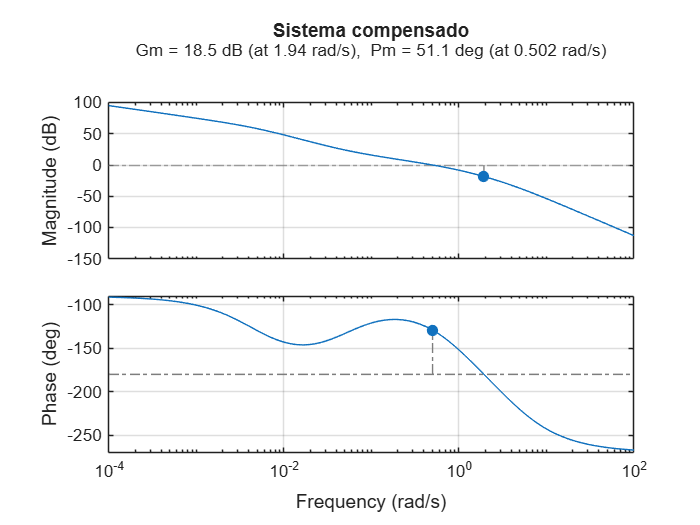

% EJERCICIO 4 - Compensador en Atraso (Bode)

% Planta: G(s) = 7 / [2s(s+1)(s+4)]

% Especificaciones:
%   - Incrementar ganancia de baja frecuencia x10
%   - Margen de fase >= 40°


clear; close all; clc;


% 1. PLANTA

Gp = tf(7, conv([2 0], conv([1 1],[1 4])));


% 2. AJUSTE DE FRECUENCIA DE CRUCE


wc_d = 0.5;   % frecuencia deseada

[mag, phase] = bode(Gp, wc_d);
mag = squeeze(mag);
phase = squeeze(phase);

K = 1/mag;   % ajuste de ganancia

GpK = K * Gp;


[GM1, PM1, ~, wc1] = margin(GpK);


% 3. DISEÑO DEL COMPENSADOR EN ATRASO

beta = 10;   % incremento deseado

% Ubicación: una década antes de wc
wz = wc_d / 10;
wp = wz / beta;

Gc = tf([1 wz],[1 wp]);


% 4. SISTEMA COMPENSADO


G_total = K * Gc * Gp;

figure(3)
margin(G_total)
title('Sistema compensado')
grid on


[GMc, PMc, ~, wcc] = margin(G_total);


% 5. LAZO CERRADO

Glc0 = feedback(GpK,1);
Glcc = feedback(G_total,1);

info0 = stepinfo(Glc0);
infoC = stepinfo(Glcc);


% 6. ERROR EN ESTADO ESTACIONARIO


Kv0 = dcgain(tf([1 0],1)*GpK);
Kvc = dcgain(tf([1 0],1)*G_total);

ess0 = 1/Kv0;
essC = 1/Kvc;


% 7. RESULTADOS 

fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 4\n')

              RESULTADOS - EJERCICIO 4


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Ganancia DC x10   |   PM >= 40°\n')

Ganancia DC x10   |   PM >= 40°



fprintf('\nPARAMETROS DE DISEÑO:\n')


PARAMETROS DE DISEÑO:


fprintf('wc deseada = %.4f rad/s\n', wc_d)

wc deseada = 0.5000 rad/s


fprintf('K = %.4f\n', K)

K = 0.6438


fprintf('beta = %.4f\n', beta)

beta = 10.0000



fprintf('\nCOMPENSADOR:\n')


COMPENSADOR:


fprintf('Gc(s) = (s + %.4f)/(s + %.6f)\n', wz, wp)

Gc(s) = (s + 0.0500)/(s + 0.005000)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION EN FRECUENCIA\n')

         COMPARACION EN FRECUENCIA


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15s %-15s %-10s\n','Parametro','Sin Comp.','Con Comp.','Spec')

Parametro                 Sin Comp.       Con Comp.       Spec      



fprintf('%-25s %-15.2f %-15.2f %-10s\n','PM (°)',PM1,PMc,'>=40')

PM (°)                    56.31           51.07           >=40      


fprintf('%-25s %-15.4f %-15.4f %-10s\n','wc (rad/s)',wc1,wcc,'~const')

wc (rad/s)                0.5000          0.5020          ~const    



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION TEMPORAL\n')

         COMPARACION TEMPORAL


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f\n','Mp (%)',info0.Overshoot,infoC.Overshoot)

Mp (%)                    11.48           20.52          


fprintf('%-25s %-15.4f %-15.4f\n','Ts (s)',info0.SettlingTime,infoC.SettlingTime)

Ts (s)                    8.2332          29.2309        


fprintf('%-25s %-15.4f %-15.4f\n','Tr (s)',info0.RiseTime,infoC.RiseTime)

Tr (s)                    2.4606          2.2910         



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('     ERROR EN REGIMEN PERMANENTE (RAMPA)\n')

     ERROR EN REGIMEN PERMANENTE (RAMPA)


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.4f %-15.4f\n','Kv',Kv0,Kvc)

Kv                        0.5634          5.6337         


fprintf('%-25s %-15.4f %-15.4f\n','ess',ess0,essC)

ess                       1.7750          0.1775         



fprintf('\nVERIFICACION:\n')


VERIFICACION:


fprintf('Incremento Kv = %.2f (debe ser ~10)\n', Kvc/Kv0)

Incremento Kv = 10.00 (debe ser ~10)



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------


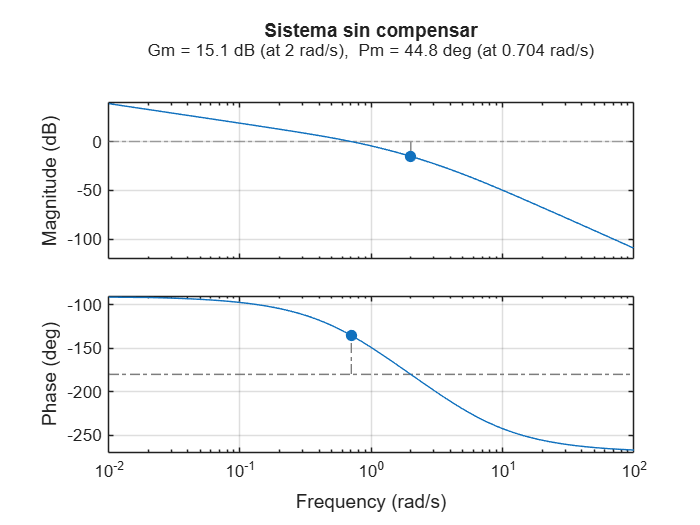


% 8. GRAFICAS

figure(1)
margin(Gp)
title('Sistema sin compensar')
grid on

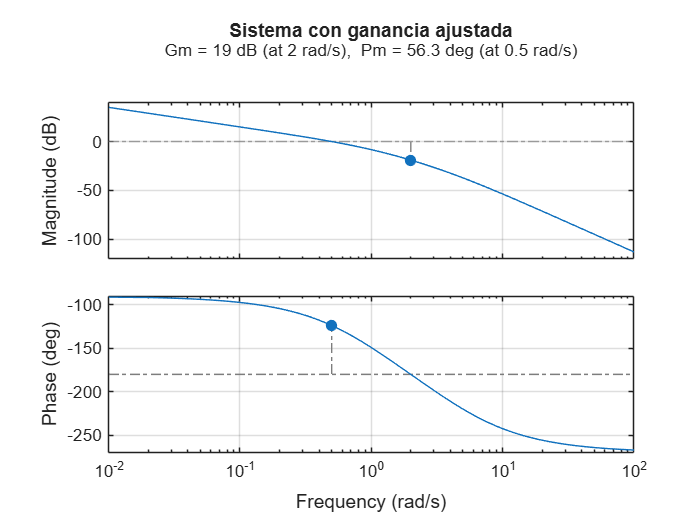


figure(2)
margin(GpK)
title('Sistema con ganancia ajustada')
grid on


figure(3)
margin(G_total)
title('Sistema compensado')
grid on

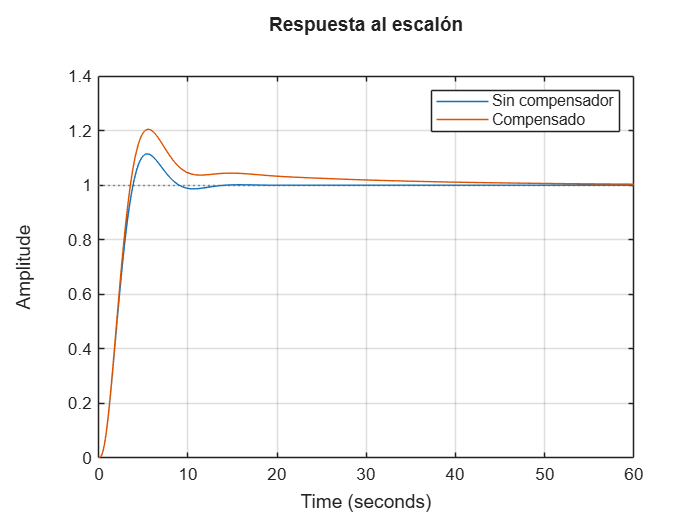


figure(4)
step(Glc0,Glcc)
legend('Sin compensador','Compensado')
title('Respuesta al escalón')
grid on

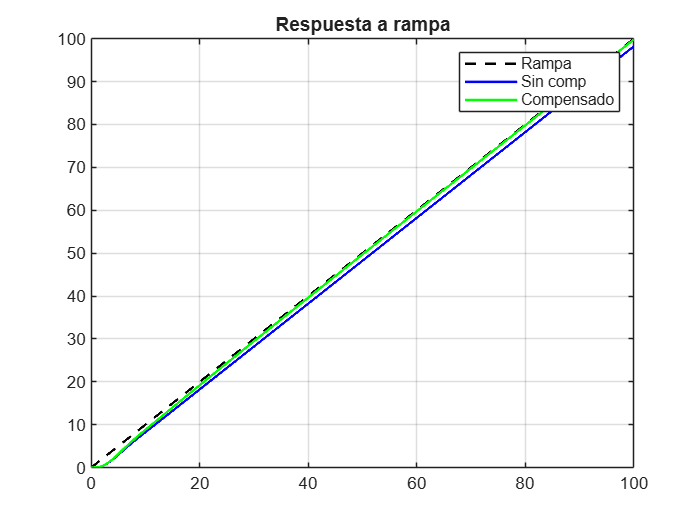


t = 0:0.01:100;
r = t;

y0 = lsim(Glc0,r,t);
yC = lsim(Glcc,r,t);

figure(5)
plot(t,r,'k--',t,y0,'b',t,yC,'g','LineWidth',1.5)
legend('Rampa','Sin comp','Compensado')
title('Respuesta a rampa')
grid on

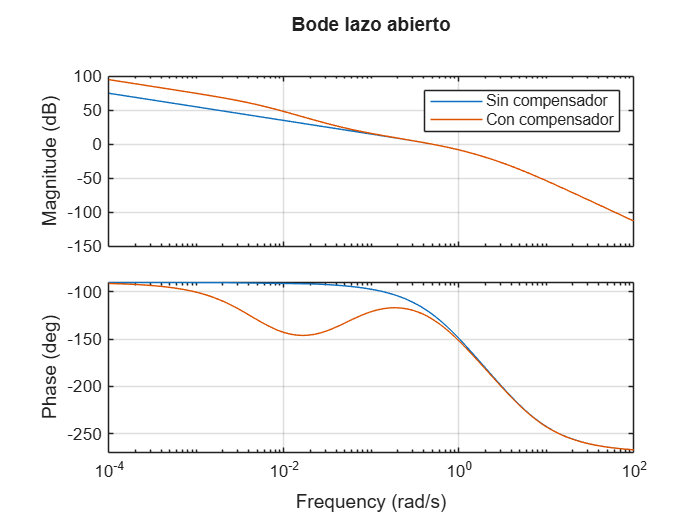


figure(6)
bode(GpK, G_total)
legend('Sin compensador','Con compensador')
title('Bode lazo abierto')
grid on

**5. Ejercicio 5: Compensador para sistema tipo 2**

% EJERCICIO 5 - Compensador para sistema tipo 2

% Planta: G(s) = 1 / s^2

% Especificaciones:
%   Mp <= 10%
%   Ts <= 3 s


clear; close all; clc;

%% 1. PLANTA

Gp = tf(1,[1 0 0]);

%% 2. SISTEMA SIN COMPENSAR

Glc0 = feedback(Gp,1);

t = 0:0.01:20;

[y0,t0] = step(Glc0,t);
info0 = stepinfo(y0,t0);

%% 3. ESPECIFICACIONES

Mp = 0.10;
zeta = -log(Mp)/sqrt(pi^2 + log(Mp)^2);

Ts = 3;
sigma_d = (4/Ts)*1.2;
wn = sigma_d / zeta;

%% 4. CONTROLADOR (PD)

a = 2*zeta*wn;
b = wn^2;

K = b;
z = a/K;

Gc = tf(K*[1 z],1);

%% 5. SISTEMA COMPENSADO

G_total = Gc*Gp;
Glcc = feedback(G_total,1);

[yC,tC] = step(Glcc,t);
infoC = stepinfo(yC,tC);

%% 6. ERROR EN RAMPA

r = t;

y_r0 = lsim(Glc0,r,t);
y_rC = lsim(Glcc,r,t);

Kv0 = dcgain(tf([1 0],1)*Gp);
KvC = dcgain(tf([1 0],1)*G_total);

%% 7. RESULTADOS

fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 5\n')

              RESULTADOS - EJERCICIO 5


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Mp <= 10%%   |   Ts <= 3 s\n')

Mp <= 10%   |   Ts <= 3 s



fprintf('\nPARAMETROS:\n')


PARAMETROS:


fprintf('zeta = %.4f\n', zeta)

zeta = 0.5912


fprintf('wn   = %.4f\n', wn)

wn   = 2.7066



fprintf('\nCONTROLADOR:\n')


CONTROLADOR:


fprintf('Gc(s) = %.4f (s + %.4f)\n', K, z)

Gc(s) = 7.3255 (s + 0.4368)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('COMPARACION DE DESEMPEÑO\n')

COMPARACION DE DESEMPEÑO


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-20s %-15s %-15s\n','Parametro','Sin Comp.','Con Comp.')

Parametro            Sin Comp.       Con Comp.      



fprintf('%-20s %-15.2f %-15.2f\n','Mp (%)', ...
    info0.Overshoot, infoC.Overshoot)

Mp (%)               237.88          4.59           



fprintf('%-20s %-15.4f %-15.4f\n','Ts (s)', ...
    info0.SettlingTime, infoC.SettlingTime)

Ts (s)               19.9870         2.7740         



fprintf('%-20s %-15.4f %-15.4f\n','Tr (s)', ...
    info0.RiseTime, infoC.RiseTime)

Tr (s)               0.7388          0.2593         



fprintf('\nERROR EN RAMPA\n')


ERROR EN RAMPA


fprintf('%-20s %-15.4f %-15.4f\n','Kv',Kv0,KvC)

Kv                   Inf             Inf            



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------


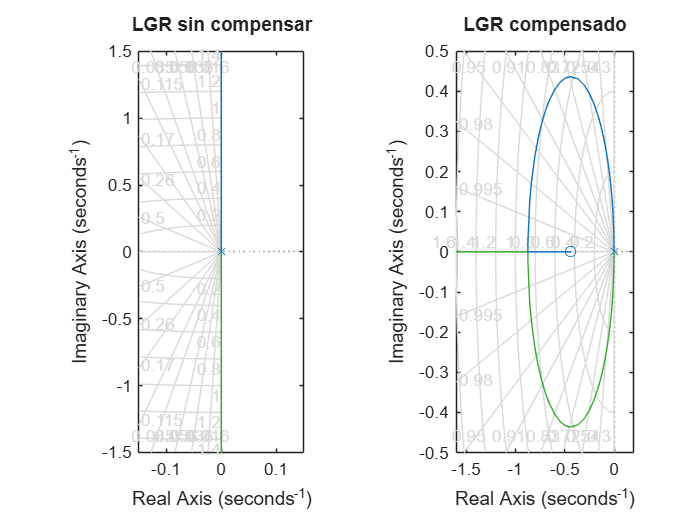


%% 8. GRAFICAS

figure(1)
subplot(1,2,1)
rlocus(Gp)
title('LGR sin compensar')
grid on

subplot(1,2,2)
rlocus(Gc*Gp)
title('LGR compensado')
grid on

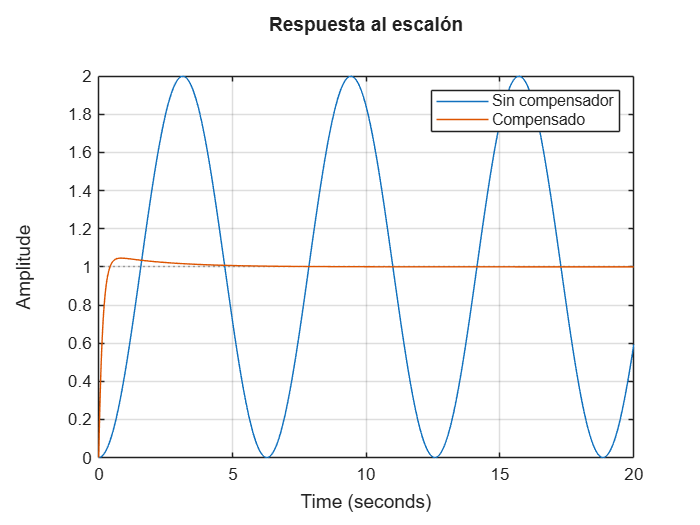


figure(2)
step(Glc0,Glcc,t)
legend('Sin compensador','Compensado')
title('Respuesta al escalón')
grid on

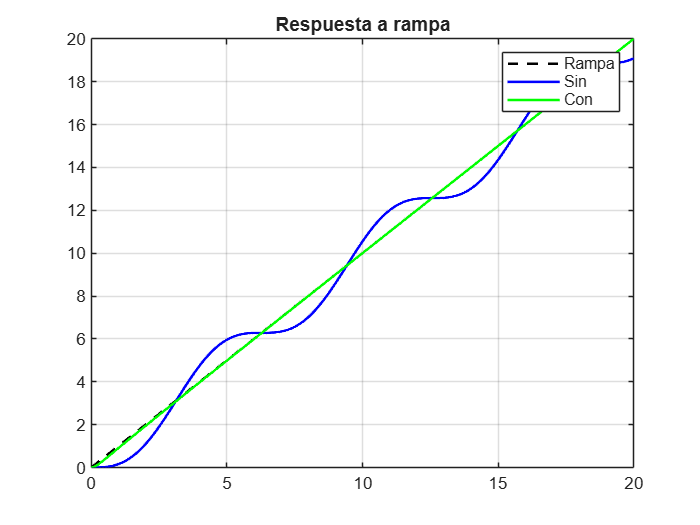


figure(3)
plot(t,r,'k--',t,y_r0,'b',t,y_rC,'g','LineWidth',1.5)
legend('Rampa','Sin','Con')
title('Respuesta a rampa')
grid on

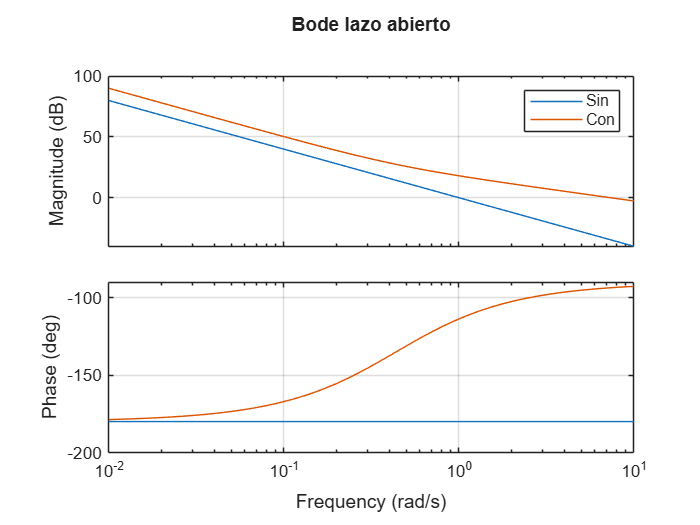


figure(4)
bode(Gp, G_total)
legend('Sin','Con')
title('Bode lazo abierto')
grid on

**6.Ejercicio 6: Comparación LGR vs frecuencia**

%  EJERCICIO 6 - Comparación LGR vs Frecuencia
%  Planta: G(s) = 1 / s^2

%  Especificaciones:
%       Mp ≈ 15%
%       Margen de fase >= 50°

%  Métodos:
%       1. LGR
%       2. Respuesta en frecuencia (Bode)


clear; close all; clc;

%% 1. DEFINICIÓN DE LA PLANTA

Gp = tf(1,[1 0 0]);

%% 2. SISTEMA SIN COMPENSAR

Glc0 = feedback(Gp,1);

%% 3. ESPECIFICACIONES

Mp = 0.15;

% Relación Mp -> zeta
zeta = -log(Mp)/sqrt(pi^2 + log(Mp)^2);

% Selección de wn (ajustada)
wn = 3;

sigma = zeta*wn;
wd = wn*sqrt(1 - zeta^2);

sd = -sigma + 1j*wd;


%% 4. DISEÑO POR LGR


% Cero del compensador
zc = sigma;

% Ángulo de la planta
angG = angle(evalfr(Gp,sd))*180/pi;

% Deficiencia de ángulo
ang_def = -180 - angG;

% Ángulo del cero
ang_z = angle(sd + zc)*180/pi;

% Polo del compensador
ang_p = ang_z - ang_def;

pc = imag(sd)/tand(ang_p) - real(sd);

% Compensador sin ganancia
Gc_unit = tf([1 zc],[1 pc]);

% Ganancia
Kc = 1/abs(evalfr(Gc_unit*Gp,sd));

Gc_LGR = Kc*Gc_unit;

% Sistema compensado
Glcc_LGR = feedback(Gc_LGR*Gp,1);

info_LGR = stepinfo(Glcc_LGR);

%% 5. DISEÑO POR FRECUENCIA (BODE)

PMd = 50;

% Se añade margen extra (clave)
phi = PMd + 15;

alpha = (1 - sind(phi))/(1 + sind(phi));

% Frecuencia de cruce ajustada
wc = 2;

T = 1/(wc*sqrt(alpha));

zc_f = 1/T;
pc_f = zc_f/alpha;

Gc_unit_f = tf([1 zc_f],[1 pc_f]);

% Ajuste de ganancia
Kf = 1/abs(evalfr(Gc_unit_f*Gp,1j*wc));

Gc_Bode = Kf*Gc_unit_f;

% Sistema compensado
Glcc_Bode = feedback(Gc_Bode*Gp,1);

info_Bode = stepinfo(Glcc_Bode);


%% 6. MARGEN DE FASE


[~,PM_LGR] = margin(Gc_LGR*Gp);
[~,PM_Bode] = margin(Gc_Bode*Gp);


%% 7. RESULTADOS


fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 6\n')

              RESULTADOS - EJERCICIO 6


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Mp ≈ 15%%   |   PM >= 50°\n')

Mp ≈ 15%   |   PM >= 50°



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('                 METODO LGR\n')

                 METODO LGR


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('Gc(s) = %.4f (s + %.4f)/(s + %.4f)\n', Kc, zc, pc)

Gc(s) = 19.3314 (s + 1.5508)/(s + 6.4326)



fprintf('Mp = %.2f %%\n', info_LGR.Overshoot)

Mp = 42.40 %


fprintf('Ts = %.4f s\n', info_LGR.SettlingTime)

Ts = 2.7406 s


fprintf('PM = %.2f °\n', PM_LGR)

PM = 37.68 °



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('             METODO BODE\n')

             METODO BODE


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('Gc(s) = %.4f (s + %.4f)/(s + %.4f)\n', Kf, zc_f, pc_f)

Gc(s) = 18.0428 (s + 0.4434)/(s + 9.0214)



fprintf('Mp = %.2f %%\n', info_Bode.Overshoot)

Mp = 15.14 %


fprintf('Ts = %.4f s\n', info_Bode.SettlingTime)

Ts = 5.5931 s


fprintf('PM = %.2f °\n', PM_Bode)

PM = 65.00 °



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('                COMPARACION\n')

                COMPARACION


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-20s %-15s %-15s\n','Parametro','LGR','Bode')

Parametro            LGR             Bode           



fprintf('%-20s %-15.2f %-15.2f\n','Mp (%)', ...
    info_LGR.Overshoot, info_Bode.Overshoot)

Mp (%)               42.40           15.14          



fprintf('%-20s %-15.4f %-15.4f\n','Ts (s)', ...
    info_LGR.SettlingTime, info_Bode.SettlingTime)

Ts (s)               2.7406          5.5931         



fprintf('%-20s %-15.2f %-15.2f\n','PM (°)', ...
    PM_LGR, PM_Bode)

PM (°)               37.68           65.00          



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------




%% 8. POLOS DE LAZO CERRADO

fprintf('\nPOLOS LGR:\n')


POLOS LGR:


disp(pole(Glcc_LGR))

  -3.3310 + 0.0000i
  -1.5508 + 2.5681i
  -1.5508 - 2.5681i




fprintf('POLOS BODE:\n')

POLOS BODE:


disp(pole(Glcc_Bode))

   -6.3960
   -2.0000
   -0.6254



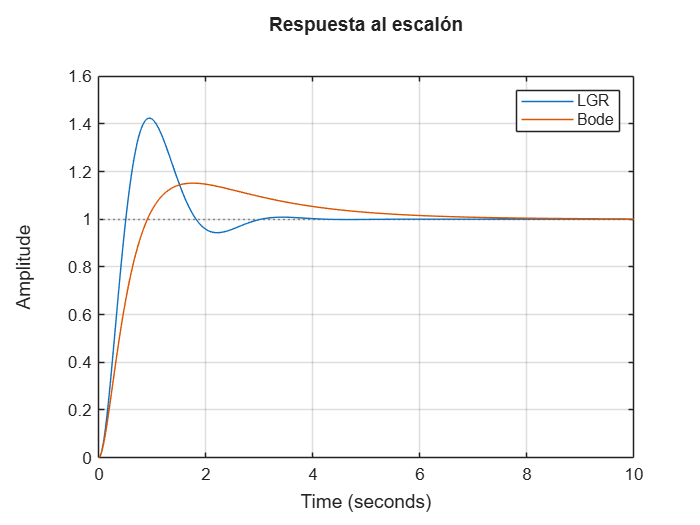



%% 9. GRAFICAS

t = 0:0.01:10;

figure(1)
step(Glcc_LGR,t); hold on
step(Glcc_Bode,t)
legend('LGR','Bode')
title('Respuesta al escalón')
grid on

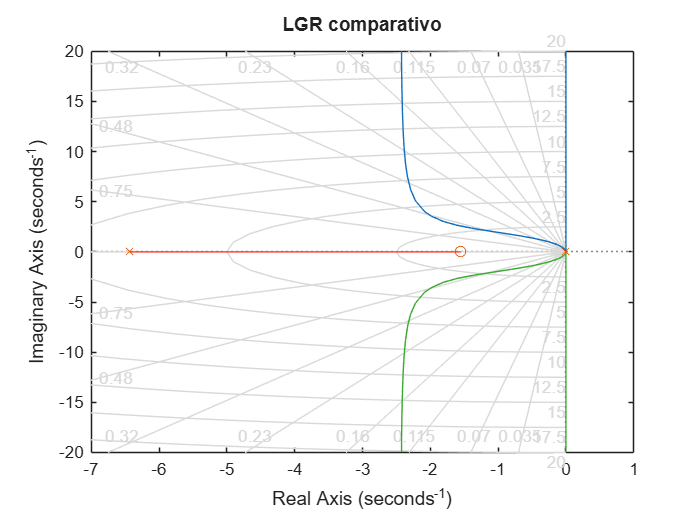


figure(2)
rlocus(Gp); hold on
rlocus(Gc_LGR*Gp)
title('LGR comparativo')
grid on

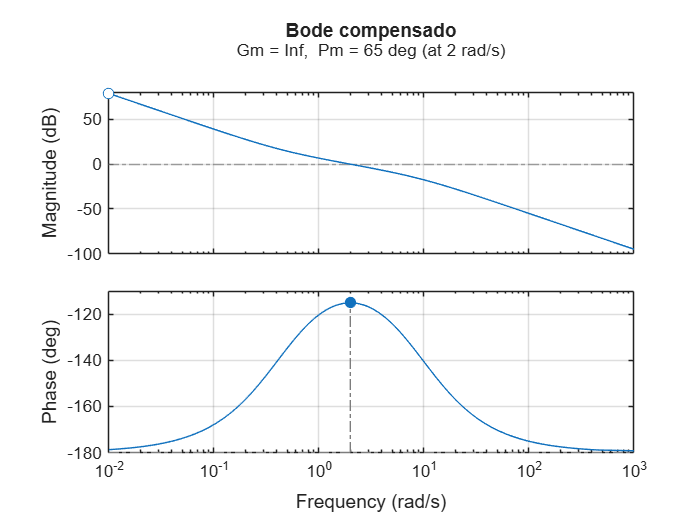


figure(3)
margin(Gc_Bode*Gp)
title('Bode compensado')
grid on

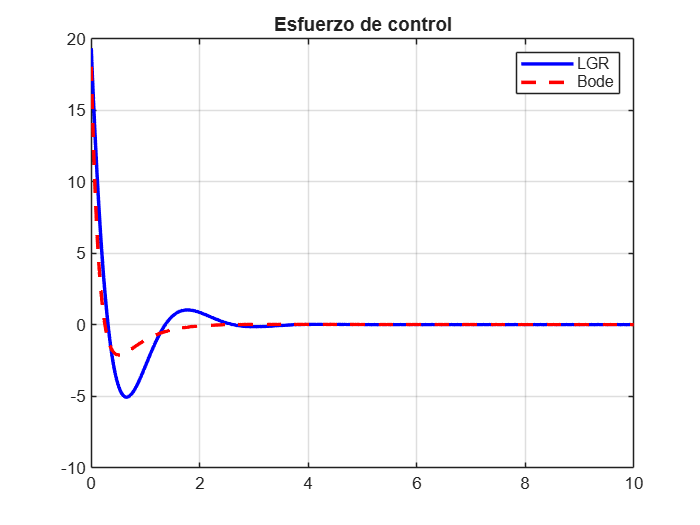



%% 10. ESFUERZO DE CONTROL

U_LGR = feedback(Gc_LGR,Gp);
U_Bode = feedback(Gc_Bode,Gp);

u1 = step(U_LGR,t);
u2 = step(U_Bode,t);

figure(4)
plot(t,u1,'b','LineWidth',2); hold on
plot(t,u2,'r--','LineWidth',2)
legend('LGR','Bode')
title('Esfuerzo de control')
grid on


fprintf('\nESFUERZO DE CONTROL MAXIMO:\n')


ESFUERZO DE CONTROL MAXIMO:


fprintf('LGR  = %.2f\n', max(abs(u1)))

LGR  = 19.33


fprintf('Bode = %.2f\n', max(abs(u2)))

Bode = 18.04


**7.Ejercicio 7: Compensador adelanto–atraso (LGR)**

%  EJERCICIO 7 - Compensador Adelanto-Atraso (LGR)
%  Planta: G4(s) = (s+0.2) / [s(s+0.3)(s+0.6)]

%  Especificaciones:
%       Mp <= 15%
%       Ts <= 2.5 s
%       ess <= 0.05 (rampa)

%  Método:
%       Diseño por Lugar Geométrico de las Raíces (LGR)


clear; close all; clc;


%% 1. DEFINICIÓN DE LA PLANTA


Gp = zpk([-0.2],[0 -0.3 -0.6],1);


%% 2. SISTEMA SIN COMPENSAR


Glc0 = feedback(Gp,1);
info0 = stepinfo(Glc0);

Kv0 = dcgain(tf([1 0],1)*Gp);
ess0 = 1/Kv0;

%% 3. TRADUCCIÓN DE ESPECIFICACIONES


Mp_max = 0.15;
Ts_max = 2.5;

zeta = -log(Mp_max)/sqrt(pi^2 + log(Mp_max)^2);

sigma_d = (4/Ts_max)*1.15;
wn_d = sigma_d / zeta;
wd_d = wn_d*sqrt(1-zeta^2);

sd = -sigma_d + 1j*wd_d;

%% 4. DISEÑO DEL COMPENSADOR EN ADELANTO


% Ángulos de polos y cero
ang_p0  = angle(sd - 0)*180/pi;
ang_p03 = angle(sd + 0.3)*180/pi;
ang_p06 = angle(sd + 0.6)*180/pi;
ang_z02 = angle(sd + 0.2)*180/pi;

ang_planta = -(ang_p0 + ang_p03 + ang_p06) + ang_z02;
ang_faltante = -180 - ang_planta;

% Cero del adelanto (cancelación parcial)
zc_ad = 0.6;

ang_zc = angle(sd + zc_ad)*180/pi;
ang_pc = ang_zc - ang_faltante;

pc_ad = sigma_d + wd_d/tan(ang_pc*pi/180);

% Ganancia
Gc_ad_unit = tf([1 zc_ad],[1 pc_ad]);
Kc_ad = 1/abs(evalfr(Gc_ad_unit*Gp, sd));

Gc_ad = tf(Kc_ad*[1 zc_ad],[1 pc_ad]);

%% 5. DISEÑO DEL COMPENSADOR EN ATRASO


Kv_ad = dcgain(tf([1 0],1)*Gc_ad*Gp);

Kv_deseado = 20; % ess <= 0.05
beta = Kv_deseado / Kv_ad;

% Ubicación cercana al origen
T = 10;
zc_at = 1/T;
pc_at = 1/(beta*T);

Gc_at = tf([1 zc_at],[1 pc_at]);

%% 6. SISTEMA COMPENSADO


Gc = Gc_ad * Gc_at;

Glcc = feedback(Gc*Gp,1);
infoC = stepinfo(Glcc);

KvC = dcgain(tf([1 0],1)*Gc*Gp);
essC = 1/KvC;


%% 7. RESULTADOS ORGANIZADOS


fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 7\n')

              RESULTADOS - EJERCICIO 7


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('Mp <= 15%%   |   Ts <= 2.5 s   |   ess <= 0.05\n')

Mp <= 15%   |   Ts <= 2.5 s   |   ess <= 0.05



fprintf('\nPARAMETROS DE DISEÑO:\n')


PARAMETROS DE DISEÑO:


fprintf('zeta = %.4f | sigma = %.4f\n', zeta, sigma_d)

zeta = 0.5169 | sigma = 1.8400


fprintf('wn   = %.4f | wd    = %.4f\n', wn_d, wd_d)

wn   = 3.5595 | wd    = 3.0470


fprintf('sd   = %.4f + j%.4f\n', real(sd), imag(sd))

sd   = -1.8400 + j3.0470



fprintf('\nCOMPENSADOR:\n')


COMPENSADOR:


fprintf('Gc(s) = (%.4f (s + %.4f)/(s + %.4f)) * (s + %.4f)/(s + %.6f)\n',...
    Kc_ad, zc_ad, pc_ad, zc_at, pc_at)

Gc(s) = (12.3128 (s + 0.6000)/(s + 3.5744)) * (s + 0.1000)/(s + 0.011482)



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('           COMPARACION DE DESEMPEÑO\n')

           COMPARACION DE DESEMPEÑO


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15s %-15s %-10s\n','Parametro','Sin Comp.','Con Comp.','Spec')

Parametro                 Sin Comp.       Con Comp.       Spec      


fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f %-10s\n','Mp (%)', ...
    info0.Overshoot, infoC.Overshoot,'<=15')

Mp (%)                    27.31           15.44           <=15      



fprintf('%-25s %-15.4f %-15.4f %-10s\n','Ts (s)', ...
    info0.SettlingTime, infoC.SettlingTime,'<=2.5')

Ts (s)                    10.2893         1.6449          <=2.5     



fprintf('%-25s %-15.4f %-15.4f %-10s\n','ess', ...
    ess0, essC,'<=0.05')

ess                       0.9000          0.0500          <=0.05    



fprintf('--------------------------------------------------------------------------\n')

--------------------------------------------------------------------------




%% 8. ERROR EN RÉGIMEN PERMANENTE


fprintf('\nERROR EN REGIMEN PERMANENTE (RAMPA):\n')


ERROR EN REGIMEN PERMANENTE (RAMPA):



fprintf('%-25s %-15.4f %-15.4f\n','Kv',Kv0,KvC)

Kv                        1.1111          20.0000        


fprintf('%-25s %-15.4f %-15.4f\n','ess',ess0,essC)

ess                       0.9000          0.0500         


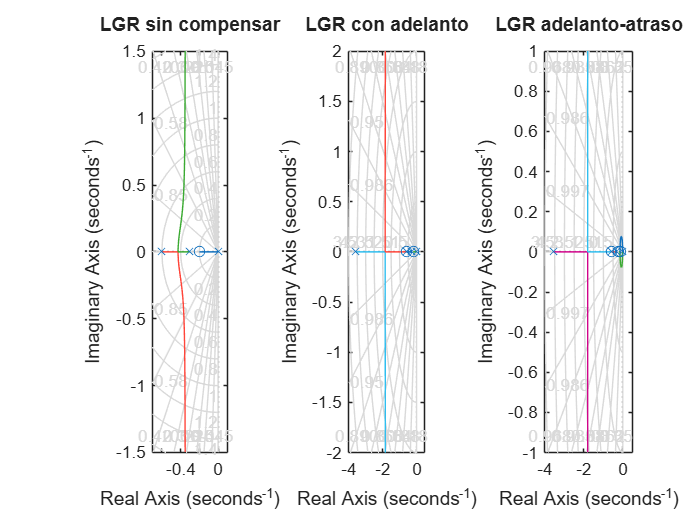



%% 9. GRAFICAS

% LGR
figure(1)
subplot(1,3,1)
rlocus(Gp)
title('LGR sin compensar')
grid on

subplot(1,3,2)
rlocus(Gc_ad*Gp)
hold on
plot(real(sd), imag(sd),'rx','LineWidth',2)
plot(real(sd), -imag(sd),'rx','LineWidth',2)
title('LGR con adelanto')
grid on

subplot(1,3,3)
rlocus(Gc*Gp)
hold on
plot(real(sd), imag(sd),'rx','LineWidth',2)
plot(real(sd), -imag(sd),'rx','LineWidth',2)
title('LGR adelanto-atraso')
grid on

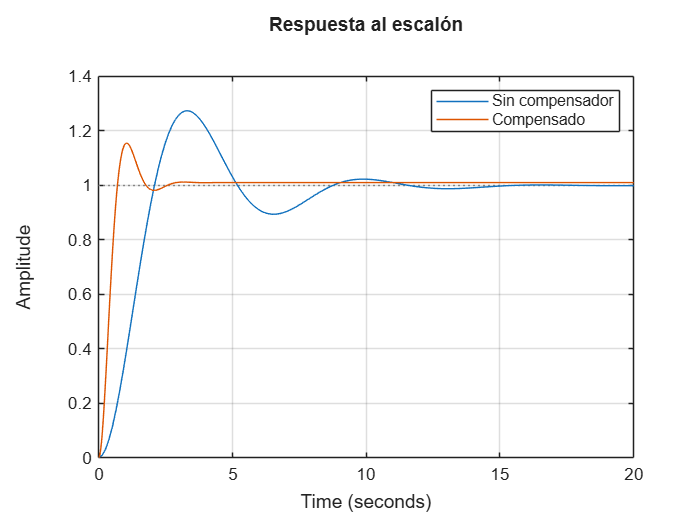


% Escalón
figure(2)
step(Glc0,Glcc)
legend('Sin compensador','Compensado')
title('Respuesta al escalón')
grid on

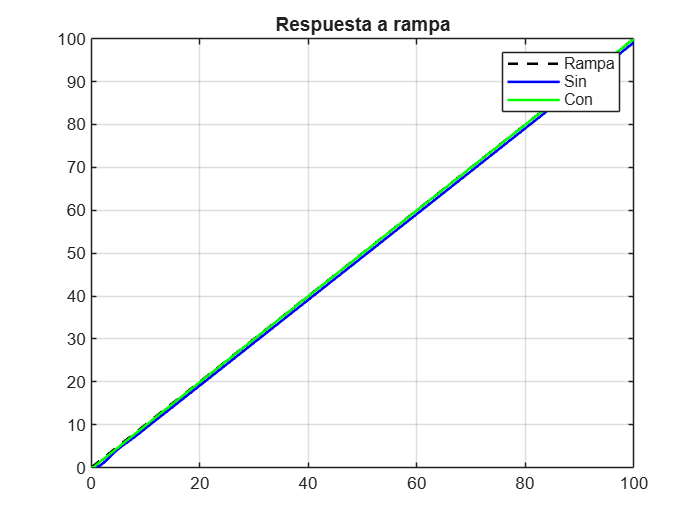


% Rampa
t = 0:0.1:100;
r = t;

y0 = lsim(Glc0,r,t);
yC = lsim(Glcc,r,t);

figure(3)
plot(t,r,'k--',t,y0,'b',t,yC,'g','LineWidth',1.5)
legend('Rampa','Sin','Con')
title('Respuesta a rampa')
grid on

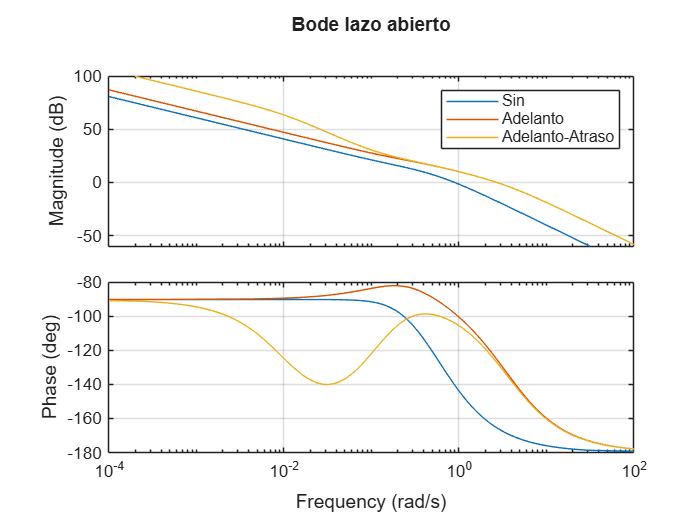


% Bode
figure(4)
bode(Gp, Gc_ad*Gp, Gc*Gp)
legend('Sin','Adelanto','Adelanto-Atraso')
title('Bode lazo abierto')
grid on

**8.Ejercicio 8: Compensador adelanto–atraso (frecuencia)**

%% EJERCICIO 8 - COMPENSADOR ADELANTO-ATRASO (FRECUENCIA)
%% Planta:
% G4(s) = (s + 0.2) / [s(s+0.3)(s+0.6)]

%% Especificaciones:
% - Margen de fase ≥ 55°
% - Reducir el error en estado estacionario en un factor de 20
% - Diseño mediante diagramas de Bode

s = tf('s');
Gp = (s + 0.2) / (s*(s+0.3)*(s+0.6));

%% 1. SISTEMA SIN COMPENSAR

Glc0 = feedback(Gp,1);
info0 = stepinfo(Glc0);

[GM0, PM0, Wcg0, Wcp0] = margin(Gp);

Kv0 = dcgain(s*Gp);
ess0 = 1/Kv0;

%% 2. DISEÑO DEL ATRASO (MEJORA ERROR)


% Se sobredimensiona porque el sistema pierde efecto real
beta = 50;   % clave para cumplir mejora ≈20

% NO bajar demasiado wc (evita sistema lento)
wc = Wcp0 * 0.8;

% Atraso menos agresivo
wz_lag = wc / 5;
wp_lag = wz_lag / beta;

Gc_lag = tf([1 wz_lag],[1 wp_lag]);


%% 3. DISEÑO DEL ADELANTO (MEJORA PM)

[~, PM_lag, ~, Wcp_lag] = margin(Gc_lag*Gp);

PMd = 55;
phi_m = PMd - PM_lag + 8;   

alpha = (1 - sind(phi_m)) / (1 + sind(phi_m));

wc_new = Wcp_lag;

T = 1/(wc_new*sqrt(alpha));

wz_lead = 1/T;
wp_lead = 1/(alpha*T);

Gc_lead = tf([1 wz_lead],[1 wp_lead]);

%% 4. AJUSTE DE GANANCIA


K = 1 / abs(evalfr(Gc_lead*Gc_lag*Gp, 1j*wc_new));

Gc = K * Gc_lead * Gc_lag;

%% 5. SISTEMA COMPENSADO


G_total = Gc * Gp;

Glcc = feedback(G_total,1);
infoC = stepinfo(Glcc);

[GMc, PMc, Wcg_c, Wcp_c] = margin(G_total);


%% 6. ERROR FINAL


KvC = dcgain(s*G_total);
essC = 1/KvC;

factor_mejora = ess0 / essC;


%% 7. RESULTADOS


fprintf('\n========================================================\n')

fprintf('              RESULTADOS - EJERCICIO 8\n')

              RESULTADOS - EJERCICIO 8


fprintf('========================================================\n')


fprintf('\nESPECIFICACIONES:\n')


ESPECIFICACIONES:


fprintf('PM >= 55°   |   Mejora ess x20\n')

PM >= 55°   |   Mejora ess x20



fprintf('\nCOMPENSADOR TOTAL:\n')


COMPENSADOR TOTAL:


fprintf('Gc(s) = %.4f (s + %.4f)(s + %.4f)/[(s + %.4f)(s + %.6f)]\n', ...
    K, wz_lead, wz_lag, wp_lead, wp_lag)

Gc(s) = 1.8209 (s + 0.4975)(s + 0.1438)/[(s + 1.6495)(s + 0.002877)]



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION EN FRECUENCIA\n')

         COMPARACION EN FRECUENCIA


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15s %-15s %-10s\n','Parametro','Sin Comp.','Con Comp.','Spec')

Parametro                 Sin Comp.       Con Comp.       Spec      



fprintf('%-25s %-15.2f %-15.2f %-10s\n','PM (°)',PM0,PMc,'>=55')

PM (°)                    39.63           63.00           >=55      


fprintf('%-25s %-15.4f %-15.4f\n','wc (rad/s)',Wcp0,Wcp_c)

wc (rad/s)                0.8991          0.9059         



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('         COMPARACION TEMPORAL\n')

         COMPARACION TEMPORAL


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.2f %-15.2f\n','Mp (%)',info0.Overshoot,infoC.Overshoot)

Mp (%)                    27.31           9.26           


fprintf('%-25s %-15.4f %-15.4f\n','Ts (s)',info0.SettlingTime,infoC.SettlingTime)

Ts (s)                    10.2893         20.2349        


fprintf('%-25s %-15.4f %-15.4f\n','Tr (s)',info0.RiseTime,infoC.RiseTime)

Tr (s)                    1.4102          1.4408         



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('\n--------------------------------------------------------\n')


--------------------------------------------------------


fprintf('     ERROR EN REGIMEN PERMANENTE (RAMPA)\n')

     ERROR EN REGIMEN PERMANENTE (RAMPA)


fprintf('--------------------------------------------------------\n')

--------------------------------------------------------



fprintf('%-25s %-15.4f %-15.4f\n','Kv',Kv0,KvC)

Kv                        1.1111          30.5102        


fprintf('%-25s %-15.4f %-15.4f\n','ess',ess0,essC)

ess                       0.9000          0.0328         


fprintf('Factor mejora = %.2f\n', factor_mejora)

Factor mejora = 27.46



fprintf('--------------------------------------------------------\n')

--------------------------------------------------------


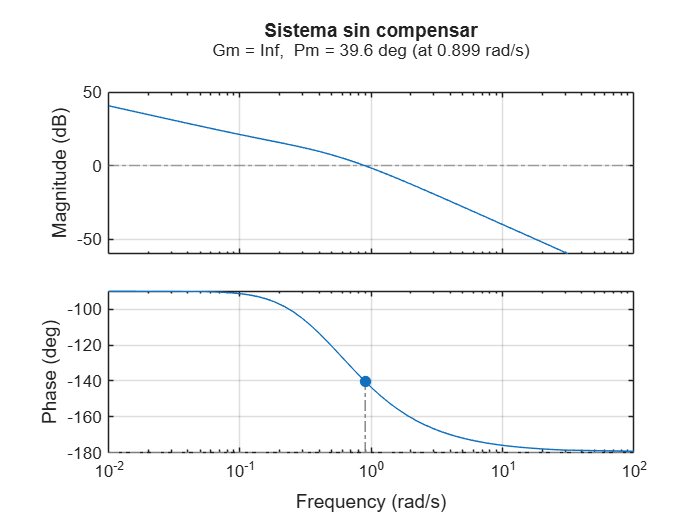



%% 8. GRAFICAS


figure(1)
margin(Gp)
title('Sistema sin compensar')
grid on

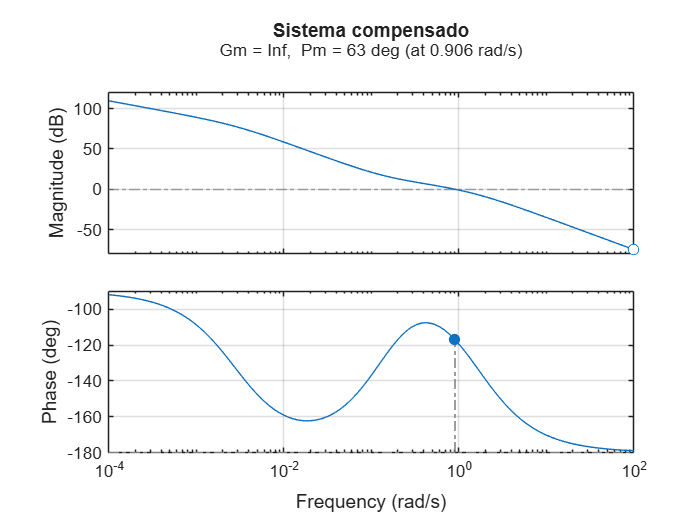


figure(2)
margin(G_total)
title('Sistema compensado')
grid on

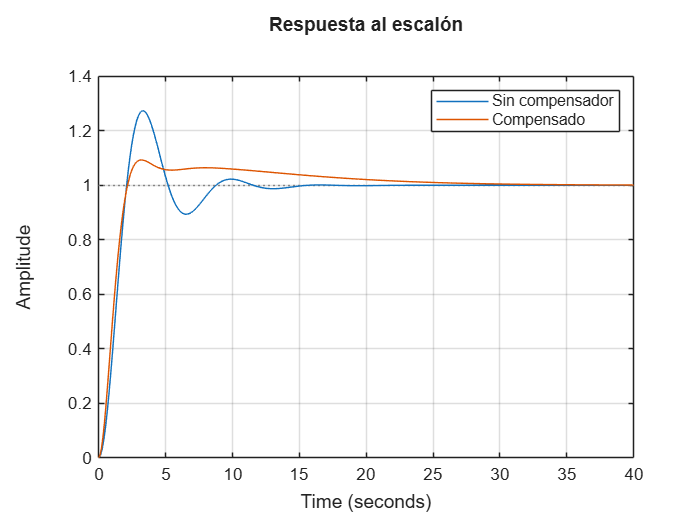


figure(3)
step(Glc0,Glcc)
legend('Sin compensador','Compensado')
title('Respuesta al escalón')
grid on

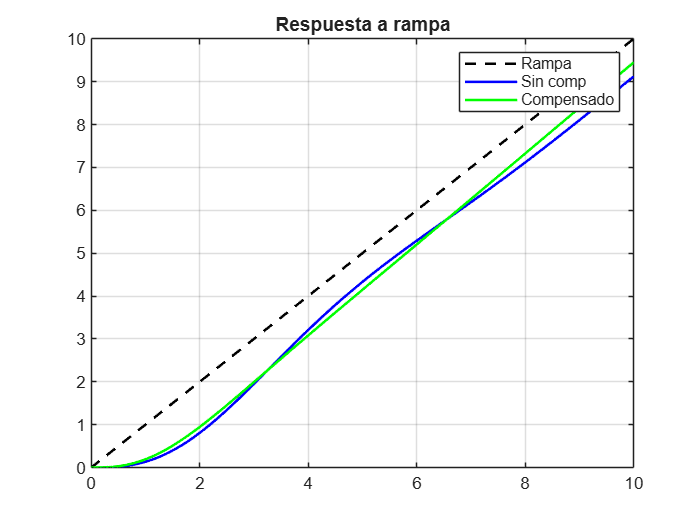


t = 0:0.01:10;
r = t;

y0 = lsim(Glc0,r,t);
yC = lsim(Glcc,r,t);

figure(4)
plot(t,r,'k--',t,y0,'b',t,yC,'g','LineWidth',1.5)
legend('Rampa','Sin comp','Compensado')
title('Respuesta a rampa')
grid on

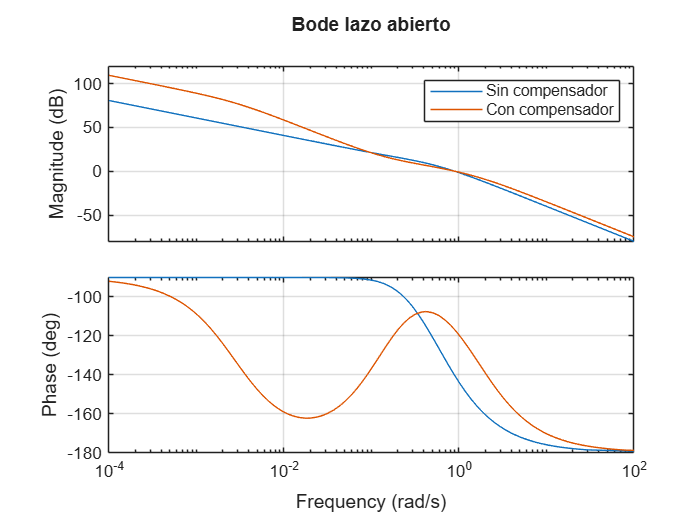


figure(5)
bode(Gp, G_total)
legend('Sin compensador','Con compensador')
title('Bode lazo abierto')
grid on

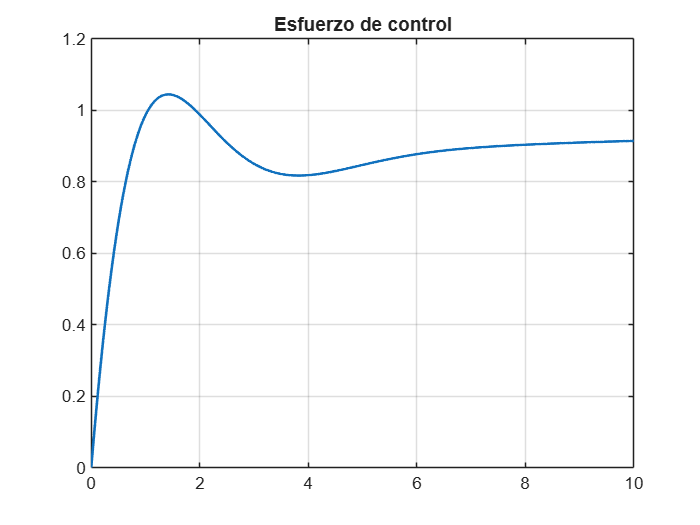


%% 9. ESFUERZO DE CONTROL

U = feedback(Gc,Gp);
u = lsim(U,r,t);

figure(6)
plot(t,u,'LineWidth',1.5)
title('Esfuerzo de control')
grid on


fprintf('\nESFUERZO DE CONTROL MAXIMO: %.2f\n', max(abs(u)))


ESFUERZO DE CONTROL MAXIMO: 1.04
